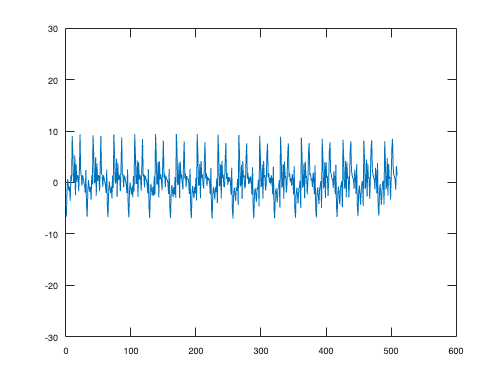

addpath 'ML_CrossValidation-SVM/01.SVM - Matlab [signal]/functions'

GROUP_0 = 'negativi';
GROUP_1 = 'positivi';

% Loading data
load('ML_CrossValidation-SVM/01.SVM - Matlab [signal]/data/signal__b.mat');

 unit = 509;
 h = figure;
 for channels = 1:32
     figure(h);
     plot(g__0(20, (1 + (channels-1)*unit) : channels*unit ));
     ylim([-30 30])
     pause(0.001);
 end


data0 = g__0; % Negativi
data1 = g__1; % Positivi
N0 = size(data0, 1); % Nr pazienti
N1 = size(data1, 1); % Nr pazienti

% Data matrix + labels'
data0 = double(data0);
data1 = double(data1);
data = double([data0; data1]); % Join the two datasets
clear data0; clear data1;

% Labels/target
labels = [zeros(1, N0) ones(1, N1)];
original_indices = 1:(N0+N1);
NNeg = N0;
NPos = N1;

% Training and parameter tuning
kernel = 'linear';
K = 5;
numvar = size(data, 2); % Nr of columns -> 509 instants * 32 channels = 16288 features

% Cross-validation index -> which patient belongs to which cluster
% (5 clusters)
indices_1 = crossvalind('Kfold', N1, K); %GROUP_1
indices_0 = crossvalind('Kfold', N0, K); %GROUP_0
index = [indices_0; indices_1];

% Metrics
accuracy = 0;
sensitivity = 0;
specificity = 0;

% ind is the cluster left out for the validation
for ind = 1:K
    disp(['K = ' num2str(ind)]);
    
    temp_train_set = true(1,size(data,1)); % All are true
    temp_train_set(index == ind) = false; % Logical array. Set to false the patients (patterns) belonging to the cluster left out for validation
    temp_test_set = ~temp_train_set; % ~ is the NOT logical operator. It could be "not(temp_train_set)"

    temp_train_indices = original_indices(temp_train_set);
    temp_test_indices = original_indices(temp_test_set);

    temp_train_labels = labels(temp_train_indices);
    temp_test_labels = labels(temp_test_indices);
    
    temp_train_data = data(temp_train_indices,:);
    temp_test_data = data(temp_test_indices,:); 

    try

        pc_tr_data = squeeze(temp_train_data(:,1:numvar));
        svmStruct = fitcsvm(pc_tr_data, temp_train_labels,...
            'KernelFunction', kernel, 'Standardize', true, ...
            'BoxConstraint', 1);
        svmStruct = compact(svmStruct);

    catch exception

        % disp('Error optimization preprocessing');
        msgString = getReport(exception)

    end

    % TESTING phase
    % Iterate over left out patients (patterns)
    for subject = 1:size(temp_test_data, 1)

        % Testing data
        temp_tdata = temp_test_data(subject,:);
        temp_tlabel = temp_test_labels(subject);

        te_data = temp_tdata;

        if size(te_data,2) == 0
            
            disp('No data!');
        
        else
            
           try
               
                pc_te_data = squeeze(te_data(:,1:numvar));

                class = predict(svmStruct, pc_te_data)';
                class = cast(class,'double');
                clear pc_te_data;

                % Caso 0 -> Negative
                if temp_tlabel == 0 && class == 0
                    accuracy = accuracy + (1/size(data, 1));
                    specificity = specificity + (1/NNeg);
                end

                % Caso 1 -> Positive
                if temp_tlabel == 1 && class == 1
                    accuracy = accuracy + (1/size(data, 1));
                    sensitivity = sensitivity + (1/NPos);
                end

                fprintf('Accuracy %.3f ', accuracy)
                fprintf('Sensitivity %.2f ', sensitivity)
                fprintf('Specificity %.2f ', specificity)
                
           catch exception
        
               disp('Error testing');
               msgString = getReport(exception)
           
           end
           
        end

        clear te_data

    end
        
end % cv

K = 1


Accuracy 0.023 

Sensitivity 0.00 

Specificity 0.05 

Accuracy 0.023 

Sensitivity 0.00 

Specificity 0.05 

Accuracy 0.045 

Sensitivity 0.00 

Specificity 0.09 

Accuracy 0.068 

Sensitivity 0.00 

Specificity 0.14 

Accuracy 0.091 

Sensitivity 0.00 

Specificity 0.18 

Accuracy 0.091 

Sensitivity 0.00 

Specificity 0.18 

Accuracy 0.114 

Sensitivity 0.05 

Specificity 0.18 

Accuracy 0.114 

Sensitivity 0.05 

Specificity 0.18 

Accuracy 0.136 

Sensitivity 0.09 

Specificity 0.18 

Accuracy 0.136 

Sensitivity 0.09 

Specificity 0.18 

K = 2


Accuracy 0.159 

Sensitivity 0.09 

Specificity 0.23 

Accuracy 0.182 

Sensitivity 0.09 

Specificity 0.27 

Accuracy 0.205 

Sensitivity 0.09 

Specificity 0.32 

Accuracy 0.227 

Sensitivity 0.09 

Specificity 0.36 

Accuracy 0.227 

Sensitivity 0.09 

Specificity 0.36 

Accuracy 0.250 

Sensitivity 0.14 

Specificity 0.36 

Accuracy 0.273 

Sensitivity 0.18 

Specificity 0.36 

Accuracy 0.273 

Sensitivity 0.18 

Specificity 0.36 

K = 3


Accuracy 0.273 

Sensitivity 0.18 

Specificity 0.36 

Accuracy 0.295 

Sensitivity 0.18 

Specificity 0.41 

Accuracy 0.318 

Sensitivity 0.18 

Specificity 0.45 

Accuracy 0.341 

Sensitivity 0.18 

Specificity 0.50 

Accuracy 0.364 

Sensitivity 0.23 

Specificity 0.50 

Accuracy 0.386 

Sensitivity 0.27 

Specificity 0.50 

Accuracy 0.409 

Sensitivity 0.32 

Specificity 0.50 

Accuracy 0.409 

Sensitivity 0.32 

Specificity 0.50 

K = 4


Accuracy 0.432 

Sensitivity 0.32 

Specificity 0.55 

Accuracy 0.455 

Sensitivity 0.32 

Specificity 0.59 

Accuracy 0.477 

Sensitivity 0.32 

Specificity 0.64 

Accuracy 0.477 

Sensitivity 0.32 

Specificity 0.64 

Accuracy 0.500 

Sensitivity 0.36 

Specificity 0.64 

Accuracy 0.523 

Sensitivity 0.41 

Specificity 0.64 

Accuracy 0.523 

Sensitivity 0.41 

Specificity 0.64 

Accuracy 0.545 

Sensitivity 0.45 

Specificity 0.64 

Accuracy 0.568 

Sensitivity 0.50 

Specificity 0.64 

K = 5


Accuracy 0.591 

Sensitivity 0.50 

Specificity 0.68 

Accuracy 0.591 

Sensitivity 0.50 

Specificity 0.68 

Accuracy 0.614 

Sensitivity 0.50 

Specificity 0.73 

Accuracy 0.614 

Sensitivity 0.50 

Specificity 0.73 

Accuracy 0.636 

Sensitivity 0.50 

Specificity 0.77 

Accuracy 0.659 

Sensitivity 0.55 

Specificity 0.77 

Accuracy 0.682 

Sensitivity 0.59 

Specificity 0.77 

Accuracy 0.682 

Sensitivity 0.59 

Specificity 0.77 

Accuracy 0.705 

Sensitivity 0.64 

Specificity 0.77 


disp('.');

.


disp('.');

.


disp('.');

.


disp('Results');

Results


disp('-----');

-----


disp(['Accuracy: ' num2str(accuracy)]);

Accuracy: 0.70455


disp(['Sensitivity: ' num2str(sensitivity)]);

Sensitivity: 0.63636


disp(['Specificity: ' num2str(specificity)]);

Specificity: 0.77273
